# Audio signal manipulation

To clear the output, go to view tab and click Clear all Output button.

% dsp01_ex_audio.m

clear all; close all;


## Audio signal acquisition

fs = 8000;       % sampling frequency (samples per second):
                 % 8000, 11025, 16000, 22050, 32000, 44100, 48000, 96000,
nBits = 8;        % number of bits per sample: 8, 16, 24, 32
channels = 1;    % number of channels: 1 or 2 (mono/stereo)
recording = audiorecorder(fs, nBits, channels); % create recording object
disp('Press any key and to record audio'); 

Press any key and to record audio


pause;
recordblocking(recording,2); % record during 2 seconds
play(recording);             % listen
audio = getaudiodata( recording, 'single' ); % import data from the audio object 

## Verification - listening, plotting

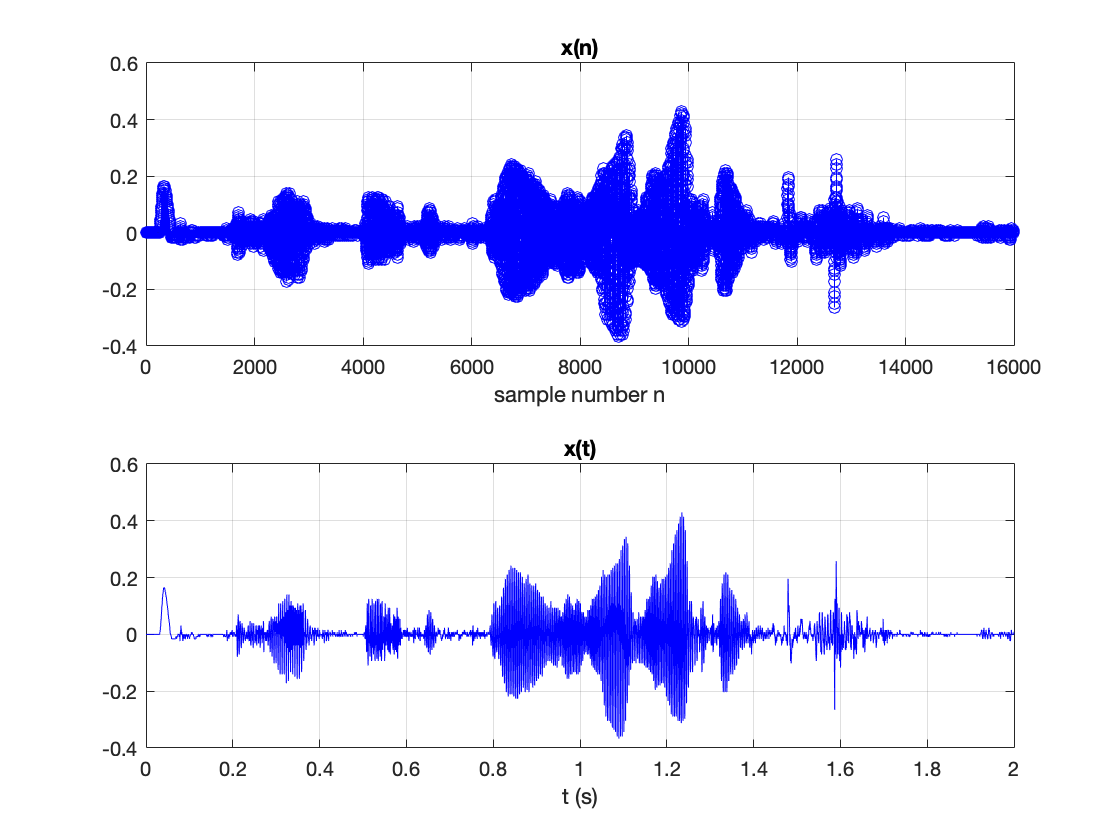

sound(audio,fs);          % play a recorded sound
x = audio; %clear audio;   % copy audio, clear audio
Nx = length(x);           % get number of samples, 
n= 0:Nx-1;                % indexes of samples
dt = 1/fs;                % calculate sampling period
t = dt*n;                 % calculate time stamps
tiledlayout(2,1);
nexttile
stem(x,'b-'); xlabel('sample number n'); title('x(n)'); grid;
nexttile
plot(t,x,'b-'); xlabel('t (s)'); title('x(t)'); grid;

## Write to disc and read from disc

audiowrite('myspeech.wav',x,fs,'BitsPerSample',nBits); % write the recording
[y,fs] = audioread('myspeech.wav');                   % read it from file
pause;
disp('Press any key and to play the signal, read from file wav'); 

Press any key and to play the signal, read from file wav


sound(y,fs);                                        % play it again